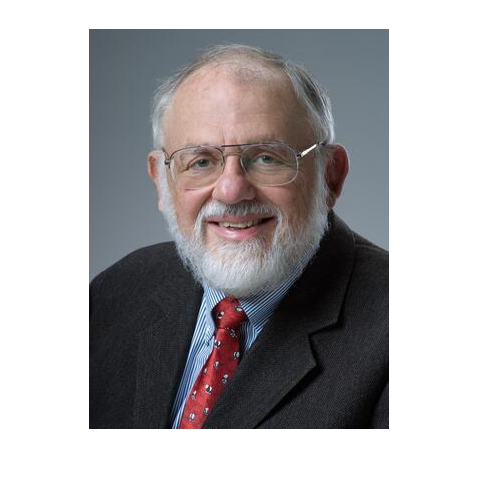

%-----------------------------------Pre-processing--------------------------------------------%
tic
% Load input image
input_image = imread('targetImage3.jpg');
input_image = im2double(input_image);

%Round size of input image to nearest 10.
[height, width, dim] = size(input_image);
input_image = imresize(input_image, [round(height,-2), round(width,-2)]);

%Show original image
target_image = input_image;
imshow(input_image);


% Define patch size in pixels
if height < 500
    patch_size = 5;
elseif height > 500 && height < 2500
    patch_size = 10;
elseif height > 2500 && height < 4500
    patch_size = 20;
elseif height > 4500
    patch_size = 50;
end

% Split input image into patches
[height, width, num_channels] = size(input_image);
num_vertical_patches = floor(height / patch_size);
num_horizontal_patches = floor(width / patch_size);

% Load the database images
dir_path = 'images_for_TNM097/';
dir_contents = dir([dir_path '*.jpeg']); % Assuming all database images are JPEG files
num_images = numel(dir_contents);
database = cell(num_images, 2);

for i = 1:num_images
    filename = dir_contents(i).name;
    filepath = fullfile(dir_path, filename);
    img = imread(filepath);
    img = im2double(img);
    img = imresize(img,[patch_size, patch_size]);
        
    % Convert the images to the LAB color space
    img_lab = mean(mean(squeeze(applycform(img, makecform('srgb2lab')))));

    % Store the image and its corresponding LAB values in the database
    database{i, 1} = img;
    database{i, 2} = img_lab;
end

%-------------------------------------Optimization--------------------------------------------%

%METHOD 1 Threshold optimization

%Define parameters
threshold_distance = 15;
num_removed = 0;
max_removed = 100;

% Reduce the database size by removing images that are too close in color space

while num_removed < max_removed && num_images > 1
    for i = 1:num_images-1
        for j = i+1:num_images
%            Calculate distance between mean CIELAB values of two images
            distance = sqrt(sum((database{i,2}-database{j,2}).^2));
%            If distance is smaller than threshold, remove one of the images
            if distance < threshold_distance
                database(j,:) = [];
                num_images = num_images - 1;
                num_removed = num_removed + 1;
                break;
            end
        end
        if num_removed >= max_removed
            break;
        end
    end
end

%METHOD 2 Index optimization

% % Initialize an array to store the error values for all images in the database
% errors = zeros(1, num_images);
% 
% % Convert the original RGB image to indexed format with a 50-color map
% [original_idx, original_map] = rgb2ind(input_image, 50);
% 
% %Convert database images to indexed format with color map from original
% for i = 1:num_images
%     db_image = database{i,1};
%     db_image = imresize(db_image, [round(height,-2), round(width,-2)]);
%     db_idx = rgb2ind(db_image, original_map);
%     errors(i) = immse(original_idx, db_idx);
% end
% 
% % Sort the error values in ascending order
% [sorted_errors, sorted_indices] = sort(errors);
% 
% % Specify the desired number of images with the least error to keep
% n = 100;
% 
% % Loop over the images in the database and delete images with large errors
% for i = num_images:-1:1
%     % Check if the current image is among the top n images with the smallest error values
%     if any(sorted_indices(1:n) == i)
%         continue;
%     else
%         database(i,:) = [];
%         num_images = num_images - 1;
%     end
% end

%-------------------------------------Image Reproduction--------------------------------------------%

for i = 1:num_vertical_patches
    for j = 1:num_horizontal_patches
        % Calculate patch coordinates
        row_start = (i - 1) * patch_size + 1;
        row_end = i * patch_size;
        col_start = (j - 1) * patch_size + 1;
        col_end = j * patch_size;
        
        % Extract patch from input image
        patch = input_image(row_start:row_end, col_start:col_end, :);
        
        % Search database for closest match
        closest_index = find_closest_match(patch, database, num_images);

        closest_image = database{closest_index,1};
        
        % Replace patch with closest match
        input_image(row_start:row_end, col_start:col_end, :) = closest_image;
        
    end
    %Display current progress
    disp([num2str(floor((i/num_vertical_patches)*100)), '%']);
end

1%
2%
3%
5%
6%
7%
8%
10%
11%
12%
13%
15%
16%
17%
18%
20%
21%
22%
23%
25%
26%
27%
28%
30%
31%
32%
33%
35%
36%
37%
38%
40%
41%
42%
43%
45%
46%
47%
48%
50%
51%
52%
53%
55%
56%
57%
58%
60%
61%
62%
63%
65%
66%
67%
68%
70%
71%
72%
73%
75%
76%
77%
78%
80%
81%
82%
83%
85%
86%
87%
88%
90%
91%
92%
93%
95%
96%
97%
98%
100%



%-------------------------------------Quality metrics--------------------------------------------%

%Define visual angle
sampDegree = visualAngle(-1,12,140,5);

InputXYZ = rgb2xyz(input_image);
targetXYZ = rgb2xyz(target_image);

%Default lightning
whitePoint = [95.5, 100, 108.9];

%Calculate S-CIELAB
LAB = scielab(sampDegree,InputXYZ,targetXYZ, whitePoint, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


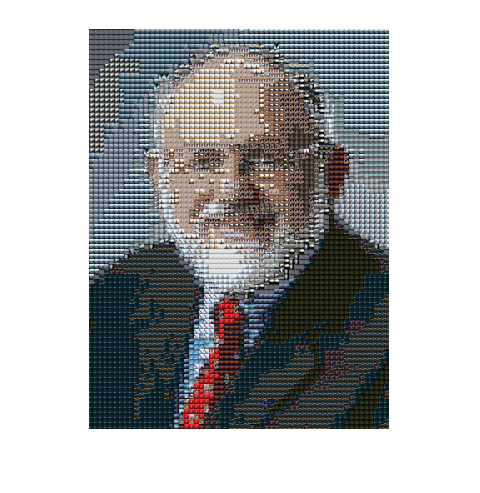

meanLab = mean(LAB(:));

%Calculate SSIM
ssim_value = ssim(input_image, target_image);

%Calculate MSE
MSE_value = immse(input_image, target_image);

%Show reproduction and display quality metrics
imshow(input_image);

disp(['SSIM between target image and original input image: ', num2str(ssim_value)]);

SSIM between target image and original input image: 0.16147


disp(['S-CIELAB between target image and original input image: ', num2str(meanLab)]);

S-CIELAB between target image and original input image: 0.4331


disp(['MSE between target image and original input image: ', num2str(MSE_value)]);

MSE between target image and original input image: 0.03055


toc

Elapsed time is 58.431475 seconds.
